# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Práctica 3. Segmentación de Imágenes (II)**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es):**

**Fecha:**

Este mlx contiene la parte de la práctica 3 relaiconada con la segmentación basada en bordes y el uso de la transformada de Hough para detectar rectas y círculos. Además de la segmentación basada en bordes, también se contempla en este mlx la transformada de Watershed. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

**Ejercicios propuestos:**

**1. Transformada Watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realize una segmentación utilizando la transformada de Watershed. ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen? En caso de que exista, intente reducirla (utilizando, por ejemplo, operadores morfológicos).

close all; clear all; clc;

imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'circles.png'));
I = im2double(I);

% 1. Convertir y Umbralizar (Lineal No Supervisada)
level = graythresh(I); % Umbral Otsu
bw = imbinarize(I, level);

% 2. Calcular la Transformada de Distancia (DT)
% Se calcula la distancia a los no-objetos (~bw)
D = bwdist(~bw);

% 3. Negar y forzar los no-objetos a -Inf
% Los picos de la DT (centros de los objetos) se convierten en valles.
D = -D; 
D(~bw) = -Inf; % Fuerzar el fondo (no-objetos) a ser los mínimos absolutos

% 4. Aplicar la Transformada Watershed
L = watershed(D);

% 5. Visualizar la Segmentación
rgb = label2rgb(L,'jet',[.5 .5 .5]);
figure('Name','(1) Transformada Watershed Directa','NumberTitle','off');
subplot(1,2,1); imshow(I); title('Original (circles.png)');
subplot(1,2,2); imshow(rgb); title(sprintf('Watershed Directa. Objetos: %d', max(L(:))));

**2. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

- Detecte los bordes utilizando el filtro de Canny. Utilice controles deslizantes (*numeric sliders*) para configurar los distintos parámetros y visualice el efecto de las diferentes configuraciones. Comente los efectos sobre los bordes del cambio de cada parámetro.

- Cierre contornos dilatando los bordes obtenidos (*imdilate*). Visualice.

- Rellene los contornos obtenidos.

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel'``y` compare los resultados (canny - sobel). Justifique.

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

close all; clear all; clc;
I = imread('coins.png'); 

% 1. Detectar Bordes con Canny (ajuste de parámetros por defecto o fino)
BW_canny = edge(I, 'canny', [0.1 0.4], 1.5); % Ejemplo de parámetros finos
60

ans = 60

figure('Name','(2) Segmentación Basada en Bordes (Canny)','NumberTitle','off');
subplot(2,3,1); imshow(BW_canny); title('1. Canny Bordes');

% 2. Cerrar Contornos con Dilatación (imdilate)
% Se usa un elemento estructurante (SE) para conectar los bordes fragmentados.
se_dilate = strel('disk', 2); % Disco de radio 2
BW_dilatada = imdilate(BW_canny, se_dilate);
subplot(2,3,2); imshow(BW_dilatada); title('2. Dilatación');

% 3. Rellenar Contornos (Holes)
% Rellena los agujeros (los objetos) dentro de los contornos cerrados.
BW_rellena = imfill(BW_dilatada, 'holes');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos');

% 4. Segmentar y Etiquetar Objetos
% Eliminar el fondo (borde de la imagen) para segmentar solo los objetos internos.
BW_sin_borde = imclearborder(BW_rellena);
[L, num_objetos] = bwlabel(BW_sin_borde);
RGB_seg = label2rgb(L, 'jet', 'w');
subplot(2,3,4); imshow(RGB_seg); title(sprintf('4. Segmentación Canny (Objetos: %d)', num_objetos));





**3. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, pinte las 7 rectas más largas de la imagen **'despacho1.jpg'**. 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre las líneas detectadas.

- Calcule el número de picos `length(P)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

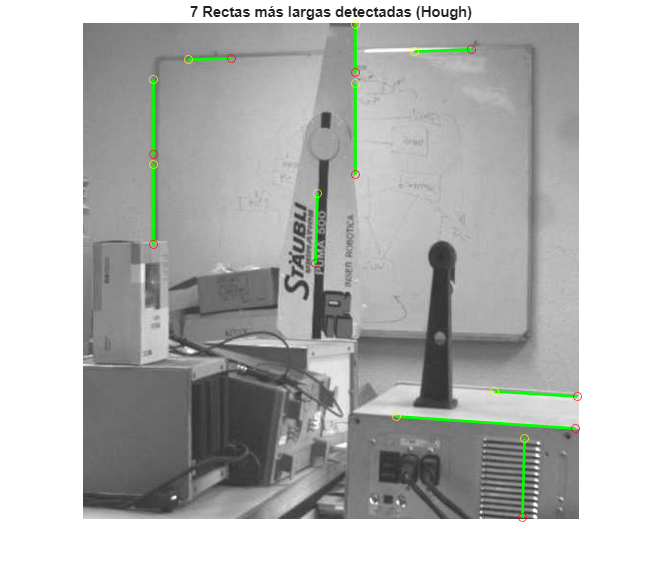

close all; clear all; clc;

imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'despacho1.jpg'));
BW = edge(rgb2gray(I), 'canny'); % Detectar bordes primero

% 1. Transformada de Hough
[H, theta, rho] = hough(BW);

% 2. Encontrar los picos (puntos con más votos)
P = houghpeaks(H, 7, 'threshold', ceil(0.3*max(H(:)))); % 7 picos (7 rectas más largas)

% 3. Encontrar las líneas (agrupar píxeles en líneas)
% Se usan MinLength y FillGap para determinar qué picos forman líneas.
lines = houghlines(BW, theta, rho, P, 'FillGap', 5, 'MinLength', 40);

% 4. Visualizar y pintar las 7 rectas
figure('Name','(3) Transformada de Hough - Rectas','NumberTitle','off');
imshow(I); hold on;
max_len = 0;

for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    
    % Pintar la recta
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');

    % Pintar los extremos
    plot(xy(1,1), xy(1,2), 'o', 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'o', 'Color', 'red');
end
title('7 Rectas más largas detectadas (Hough)');
hold off;

hola=50;

**4. Detección de círculos utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y pinte el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?

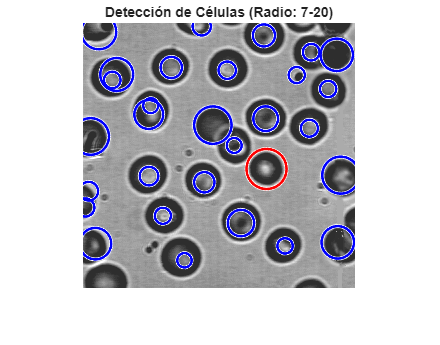


 

imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'blood1.tif'));
I_gray = im2gray(I);

% 1. (Opcional) Pre-procesamiento: Invertir y Umbralizar (si es necesario)
% Las células son más brillantes que el fondo en 'blood1.tif'.
% Detectaremos bordes sobre la imagen original.
BW = edge(I_gray, 'canny'); 

% 2. Detección de Círculos (Radios entre 7 y 20 píxeles)
radio_range = [7 20];
[centers, radii] = imfindcircles(BW, radio_range, 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);

% 3. Visualizar los resultados
figure('Name','(4) Transformada de Hough - Círculos (Células)','NumberTitle','off');
imshow(I);
title(sprintf('Detección de Células (Radio: %d-%d)', radio_range(1), radio_range(2)));
hold on;

% 4. Resaltar la célula más grande
[max_radius, max_idx] = max(radii);
centers_max = centers(max_idx,:);
radii_max = radii(max_idx);

% Pintar todas las células (en azul)
viscircles(centers, radii, 'EdgeColor', 'b');

% Pintar la célula más grande (en rojo)
viscircles(centers_max, radii_max, 'EdgeColor', 'r', 'LineWidth', 2); 
hold off;